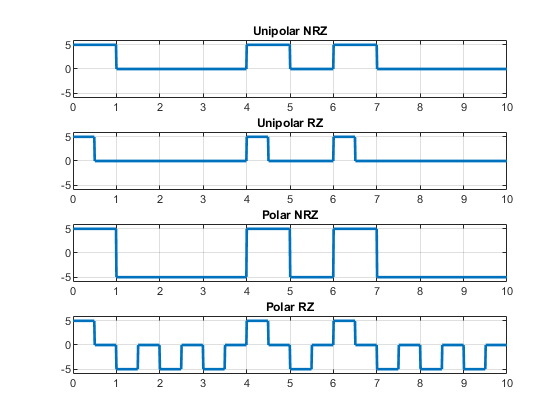

N=10;
a=floor(2*rand(1,N));
A=5;
Tb=1;
fs=100;

%Unipolar NRZ
U=[];
for k=1:N
    U=[U A*a(k)*ones(1,fs)];
end

%Unipolar RZ
U_rz=[];
for k=1:N
    c=ones(1,fs/2);
    b=zeros(1,fs/2);
    p=[c b];
    U_rz=[U_rz A*a(k)*p];
end

%Polar NRZ
P=[];
for k=1:N
    P=[P ((-1)^(a(k)+1))*A*ones(1,fs)];
end

%Polar RZ
P_rz=[];
for k=1:N
    c=ones(1,fs/2);
    b=zeros(1,fs/2);
    p=[c b];
    P_rz=[P_rz ((-1)^(a(k)+1))*A*p];
end

%Bipolar NRZ
B=[];
count=-1;
for k=1:N
    if a(k)==1
        if count==-1
            B=[B A*a(k)*ones(1,fs)];
            count=1;
        else
            B=[B -A*a(k)*ones(1,fs)];
            count=-1;
        end
    else
        B=[B A*a(k)*ones(1,fs)];
    end
end

%Bipolar RZ
B_rz=[];
count=-1;
for k=1:N
    if a(k)==1
        if count==-1
            B_rz=[B_rz A*a(k)*ones(1,fs/2) zeros(1,fs/2)];
            count=1;
        else
            B_rz=[B_rz -A*a(k)*ones(1,fs/2) zeros(1,fs/2)];
            count=-1;
        end
    else
        B_rz=[B_rz A*a(k)*ones(1,fs)];
    end
end

%Manchster Code
M=[];
for k=1:N
    c=ones(1,fs/2);
    b=-1*ones(1,fs/2);
    p=[c b];
    M=[M ((-1)^(a(k)+1))*A*p];
end
    
T=linspace(0,N*Tb,length(U));

figure(1);

subplot(4,1,1);
plot(T,U,'LineWidth',2);
axis([0 N*Tb -6 6]);
title('Unipolar NRZ');
grid on;

subplot(4,1,2);
plot(T,U_rz,'LineWidth',2);
axis([0 N*Tb -6 6]);
title('Unipolar RZ');
grid on;

subplot(4,1,3);
plot(T,P,'LineWidth',2);
axis([0 N*Tb -6 6]);
title('Polar NRZ');
grid on;

subplot(4,1,4);
plot(T,P_rz,'LineWidth',2);
axis([0 N*Tb -6 6]);
title('Polar RZ');
grid on;

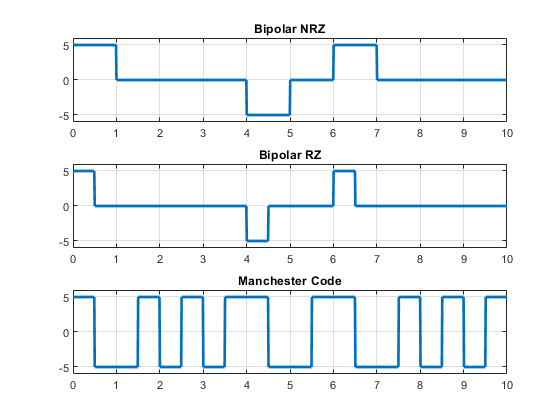


figure(2);

subplot(3,1,1);
plot(T,B,'LineWidth',2);
axis([0 N*Tb -6 6]);
title('Bipolar NRZ');
grid on;

subplot(3,1,2);
plot(T,B_rz,'LineWidth',2);
axis([0 N*Tb -6 6]);
title('Bipolar RZ');
grid on;

subplot(3,1,3);
plot(T,M,'LineWidth',2);
axis([0 N*Tb -6 6]);
title('Manchester Code');
grid on;